# Lab2

dt = 0.01;
t = -10 : dt : 10;

## Esercizio 1 (ii)

Rect = integrale(t, rect(t));
Tri = integrale(t, tri(t));
Sin = integrale(t, sin(2 * pi * t / 3));
energiaRect = energia(t, rect(t));
energiaTri = energia(t, tri(t));
energiaSin = 1 / 3 * energia(t, sin(2 * pi * t / 3));
potenzaRect = potenza(t, rect(t));
potenzaTri = potenza(t, tri(t));
potenzaSin = 1 / 3 * potenza(t, sin(2 * pi * t / 3));

## Esercizio 2 (i)

x1 = 3 * rect(t);
y1 = tri(t);
normaX1 = norma2(t, x1);
normaY1 = norma2(t, y1);
distanzaX1Y1 = distanza2(t, x1, y1);
distanzaX1X1 = distanza2(t, x1, x1);
distanzaY1X1 = distanza2(t, y1, x1);
distanzaY1Y1 = distanza2(t, y1, y1);
formaBilineareX1Y1 = formaBilineare(t, x1, y1);
formaBilineareX1X1 = formaBilineare(t, x1, x1);
formaBilineareY1X1 = formaBilineare(t, y1, x1);
formaBilineareY1Y1 = formaBilineare(t, y1, y1);

## Esercizio 2 (ii)

x2 = tri(t);
y2 = tri(t - 1);
normaX2 = norma2(t, x2);
normaY2 = norma2(t, y2);
distanzaX2Y2 = distanza2(t, x2, y2);
distanzaX2X2 = distanza2(t, x2, x2);
distanzaY2X2 = distanza2(t, y2, x2);
distanzaY2Y2 = distanza2(t, y2, y2);
formaBilineareX2Y2 = formaBilineare(t, x2, y2);
formaBilineareX2X2 = formaBilineare(t, x2, x2);
formaBilineareY2X2 = formaBilineare(t, y2, x2);
formaBilineareY2Y2 = formaBilineare(t, y2, y2);

## Esercizio 2 (iii)

x3 = 2 * exp(-abs(t));
y3 = 1i * tri(t);
normaX3 = norma2(t, x3);
normaY3 = norma2(t, y3);
distanzaX3Y3 = distanza2(t, x3, y3);
distanzaX3X3 = distanza2(t, x3, x3);
distanzaY3X3 = distanza2(t, y3, x3);
distanzaY3Y3 = distanza2(t, y3, y3);
formaBilineareX3Y3 = formaBilineare(t, x3, y3);
formaBilineareX3X3 = formaBilineare(t, x3, x3);
formaBilineareY3X3 = formaBilineare(t, y3, x3);
formaBilineareY3Y3 = formaBilineare(t, y3, y3);

## Esercizio 3 (i)

B = zeros(20, length(t));
for k = 1:height(B)
	B(k, :) = rect(t - k + 21 / 2);
end

## Esercizio 3 (ii)

G = zeros(height(B), height(B));
for k = 1:height(G)
	for l = 1:height(G)
		G(k, l) = formaBilineare(t, B(k, :), B(l, :));
	end
end	% La matrice G è la matrice identità, quindi B è ortonormale

## Esercizio 3 (iii)

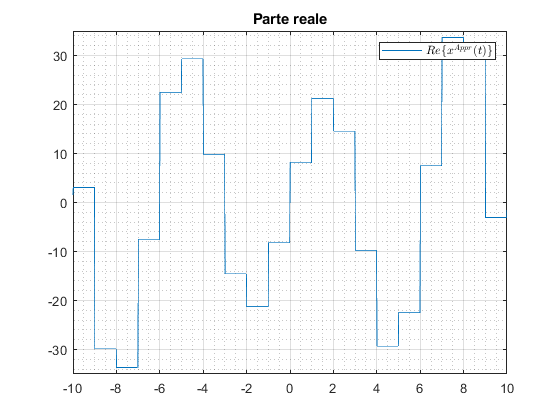

x = 10 * sin(t) .* (1 + sqrt(abs(t)));
Appr_x = zeros(size(t));
for k = 1:height(B)
	Appr_x = Appr_x + formaBilineare(t, x, B(k, :)) * B(k, :);
end
rappresentaUnSegnale(t, Appr_x, 'x^{Appr}(t)');

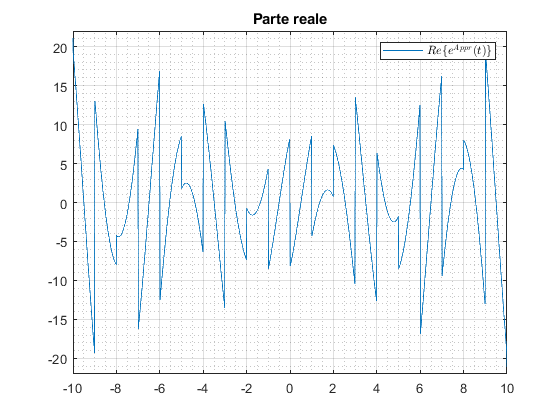

Appr_err = x - Appr_x;
rappresentaUnSegnale(t, Appr_err, 'e^{Appr}(t)');

## Esercizio 4 (i)

B2 = zeros(21, length(t));
for k = 1:height(B2)
	B2(k, :) = tri(t - k + 11);
end
G2 = zeros(height(B2), height(B2));
for k = 1:height(G2)
	for l = 1:height(G2)
		G2(k, l) = formaBilineare(t, B2(k, :), B2(l, :));
	end
end	% La matrice G2 non è la matrice identità, quindi B2 non è ortonormale

## Esercizio 4 (ii)

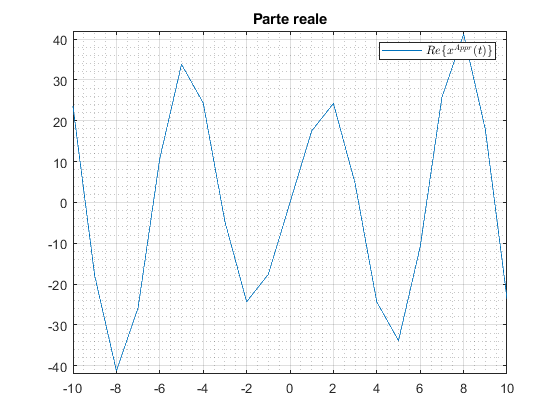

B3 = ortonormalizzazioneDiGramSchmidt(t, B2);
G3 = zeros(height(B3), height(B3));
for k = 1:height(G3)
	for l = 1:height(G3)
		G3(k, l) = formaBilineare(t, B3(k, :), B3(l, :));
	end
end	% La matrice G3 è la matrice identità, quindi B3 è ortonormale
Appr2_x = zeros(size(t));
for k = 1:height(B3)
	Appr2_x = Appr2_x + formaBilineare(t, x, B3(k, :)) * B3(k, :);
end
rappresentaUnSegnale(t, Appr2_x, 'x^{Appr}(t)');

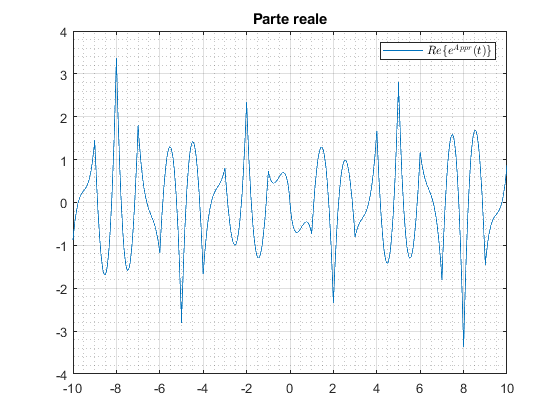

Appr2_err = x - Appr2_x;
rappresentaUnSegnale(t, Appr2_err, 'e^{Appr}(t)');

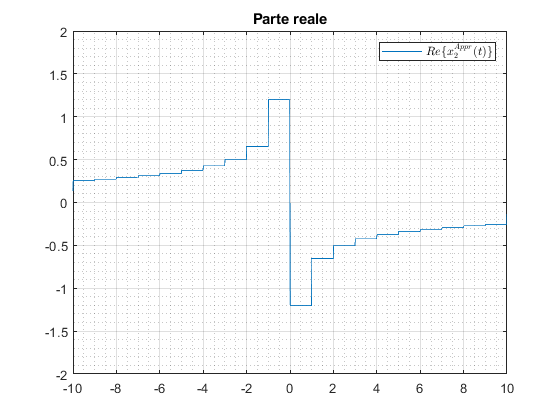

x2 = 10 * sin(2 * pi * t) .* (1 + sqrt(abs(t)));
Appr_x2 = zeros(size(t));
for k = 1:height(B)
	Appr_x2 = Appr_x2 + formaBilineare(t, x2, B(k, :)) * B(k, :);
end
rappresentaUnSegnale(t, Appr_x2, 'x_{2}^{Appr}(t)');

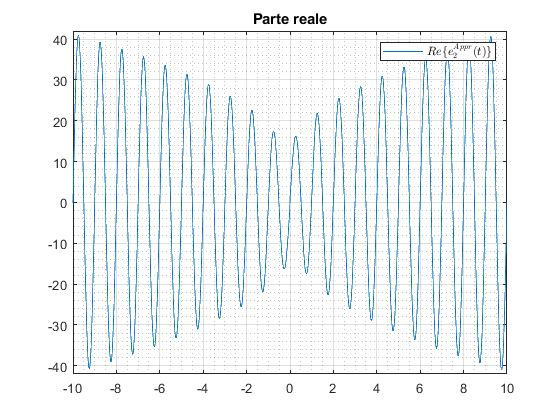

Appr_err2 = x2 - Appr_x2;
rappresentaUnSegnale(t, Appr_err2, 'e_{2}^{Appr}(t)');

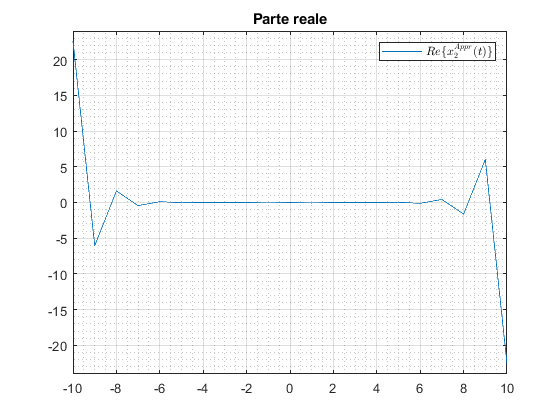

Appr2_x2 = zeros(size(t));
for k = 1:height(B3)
	Appr2_x2 = Appr2_x2 + formaBilineare(t, x2, B3(k, :)) * B3(k, :);
end
rappresentaUnSegnale(t, Appr2_x2, 'x_{2}^{Appr}(t)');

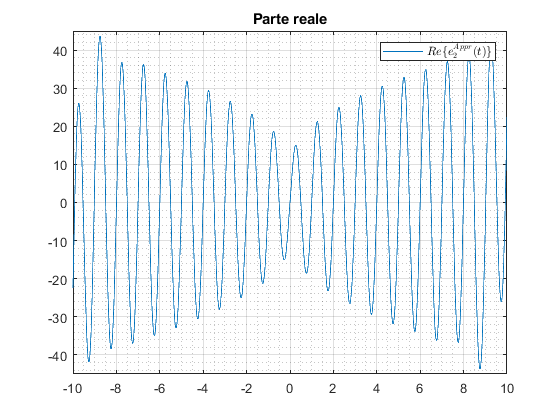

Appr2_err2 = x2 - Appr2_x2;
rappresentaUnSegnale(t, Appr2_err2, 'e_{2}^{Appr}(t)');

% La frequenza del segnale x2 è troppo alta perché la base riesca ad
% approssimarla in modo corretto, perciò accade che la base non veda
% correttamente il segnale e determini così un aumento dell'errore
% dell'approssimazione.